## Spectrogram Generation 

### Control Signals

% Locate the TVALID and TLAST control signals of the FFT
fft_out_tvalid = out.TVALID

fft_out_tvalid =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


find(fft_out_tvalid == 1, 1)

ans = 4237

fft_out_tlast = out.TLAST

fft_out_tlast =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


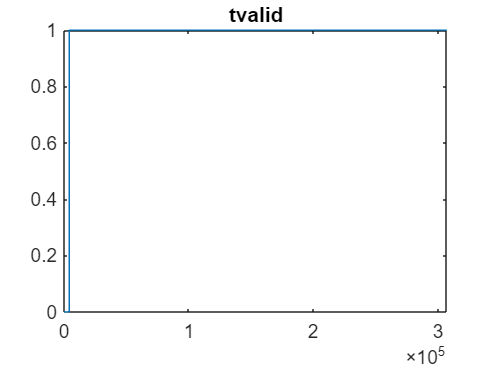

plot(1:length(fft_out_tvalid),fft_out_tvalid)
title('tvalid')

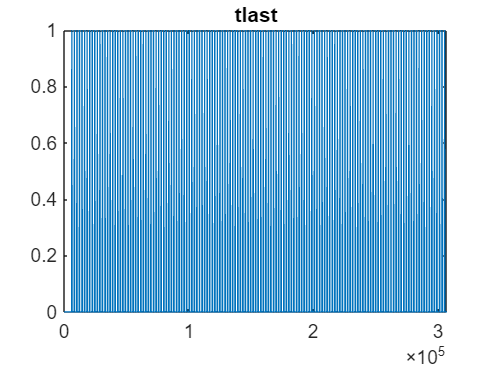

plot(1:length(fft_out_tlast),fft_out_tlast)
title('tlast')


% Set TLAST signal from first TVALID to keep it with data output
fft_out_tlast = fft_out_tlast(find(fft_out_tvalid == 1, 1):end)

fft_out_tlast =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


find(fft_out_tlast,1,'first')

ans = 2048

### HDL block floating point 

% Locate the FFT data output
fft_out_log_ = out.FFT_out_log

fft_out_log_ =      0
     0
     0
     0
  -512
  -512
  -512
  -512
  -512
  -512


% Only keep the valid samples
fft_out_log = fft_out_log_(find(fft_out_tvalid == 1, 1):end)

fft_out_log =  -156.5355
 -153.0136
 -153.0136
 -156.5355
 -153.0136
 -153.0136
 -153.0136
 -149.4918
 -149.4918
 -153.0136


% Zero-pad if neccessary to ensure # samples is an integer multiple of the
% window size (required for easier spectrogram plotting)
fft_length_before_zero_padding = (ceil(length(fft_out_log)/N))

fft_length_before_zero_padding = 148


% Set the zero-padded values to the minimum value of the valid samples
fft_out_log(length(fft_out_log)+1:fft_length_before_zero_padding*N)=min(fft_out_log)

fft_out_log =  -156.5355
 -153.0136
 -153.0136
 -156.5355
 -153.0136
 -153.0136
 -153.0136
 -149.4918
 -149.4918
 -153.0136



% Determine key parameters
Total_Num_Samples = length(fft_out_log)

Total_Num_Samples = 303104

Num_Segments = Total_Num_Samples/N

Num_Segments = 148


% Create the frequency and time axis for both spectrograms
f_axis_1N = (n/N*fs)/1e6; % From 0 -> fs
f_axis_1N_ = (-N/2:N/2-1)*(fs/N)/1e6; % From -fs/2 -> fs/2 (combined with fftshift for centring DC - as high f is just a spectral replication of -ve f)
t_axis_1N = linspace(0,Total_Num_Samples/fs,Num_Segments)

t_axis_1N =          0    0.0000    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0012    0.0013    0.0013    0.0014    0.0014    0.0014    0.0015    0.0015    0.0016    0.0016    0.0016    0.0017    0.0017    0.0018    0.0018    0.0019    0.0019    0.0019    0.0020    0.0020


t_axis_1N = 1e3.*t_axis_1N

t_axis_1N =          0    0.0412    0.0825    0.1237    0.1650    0.2062    0.2474    0.2887    0.3299    0.3711    0.4124    0.4536    0.4949    0.5361    0.5773    0.6186    0.6598    0.7011    0.7423    0.7835    0.8248    0.8660    0.9073    0.9485    0.9897    1.0310    1.0722    1.1134    1.1547    1.1959    1.2372    1.2784    1.3196    1.3609    1.4021    1.4434    1.4846    1.5258    1.5671    1.6083    1.6495    1.6908    1.7320    1.7733    1.8145    1.8557    1.8970    1.9382    1.9795    2.0207


f_axis = repmat(f_axis_1N,1,Num_Segments)

f_axis =          0    0.0244    0.0488    0.0732    0.0977    0.1221    0.1465    0.1709    0.1953    0.2197    0.2441    0.2686    0.2930    0.3174    0.3418    0.3662    0.3906    0.4150    0.4395    0.4639    0.4883    0.5127    0.5371    0.5615    0.5859    0.6104    0.6348    0.6592    0.6836    0.7080    0.7324    0.7568    0.7812    0.8057    0.8301    0.8545    0.8789    0.9033    0.9277    0.9521    0.9766    1.0010    1.0254    1.0498    1.0742    1.0986    1.1230    1.1475    1.1719    1.1963


f_axis_ = repmat(f_axis_1N_,1,Num_Segments)

f_axis_ =   -25.0000  -24.9756  -24.9512  -24.9268  -24.9023  -24.8779  -24.8535  -24.8291  -24.8047  -24.7803  -24.7559  -24.7314  -24.7070  -24.6826  -24.6582  -24.6338  -24.6094  -24.5850  -24.5605  -24.5361  -24.5117  -24.4873  -24.4629  -24.4385  -24.4141  -24.3896  -24.3652  -24.3408  -24.3164  -24.2920  -24.2676  -24.2432  -24.2188  -24.1943  -24.1699  -24.1455  -24.1211  -24.0967  -24.0723  -24.0479  -24.0234  -23.9990  -23.9746  -23.9502  -23.9258  -23.9014  -23.8770  -23.8525  -23.8281  -23.8037


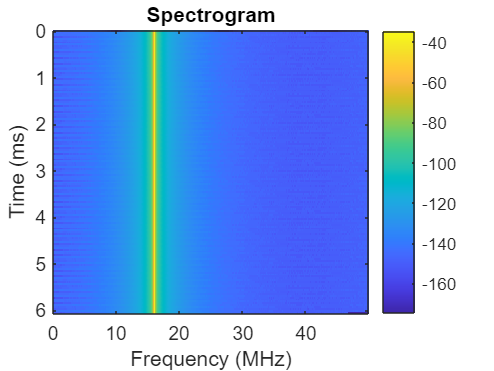


% Fill in the arrays to plot the spectrograms
for i=1:Num_Segments
    index = (i-1)*N+1 : i*N;
    t_axis(index) = t_axis_1N(i);   
    Data(i,:) = fft_out_log(index);
    Data_shift(i,:) = fftshift(Data(i,:));
end

% Plot spectrograms 
figure;
imagesc(f_axis,t_axis,Data)
title('Spectrogram')
xlabel('Frequency (MHz)')
ylabel('Time (ms)')
colorbar

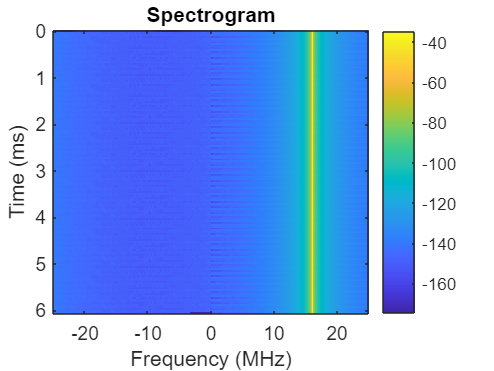

figure;
imagesc(f_axis_,t_axis,Data_shift)
title('Spectrogram')
xlabel('Frequency (MHz)')
ylabel('Time (ms)')
colorbar


% Plot 1st spectrum 
first_spectrum = fft_out_log(1:find(fft_out_tlast,1,'first')) % Or just Data(1,:)

first_spectrum =  -156.5355
 -153.0136
 -153.0136
 -156.5355
 -153.0136
 -153.0136
 -153.0136
 -149.4918
 -149.4918
 -153.0136


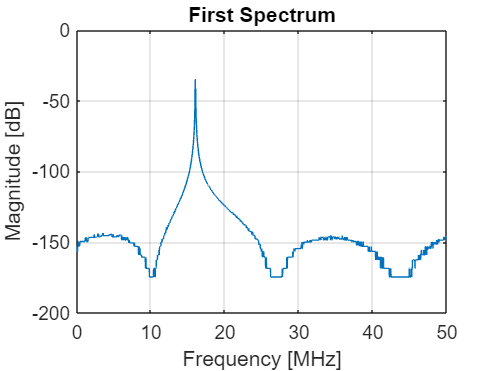

figure;
plot(f_axis_1N,first_spectrum);
xlabel('Frequency [MHz]');
ylabel('Magnitude [dB]');
title('First Spectrum');
grid on;

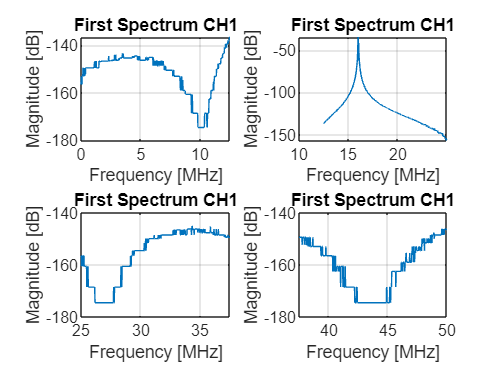

figure;
subplot(2,2,1);
plot(f_axis_1N(1+512*0:512*1),first_spectrum(1+512*0:512*1));
xlabel('Frequency [MHz]');
ylabel('Magnitude [dB]');
title('First Spectrum CH1');
grid on;
subplot(2,2,2);
plot(f_axis_1N(1+512*1:512*2),first_spectrum(1+512*1:512*2));
xlabel('Frequency [MHz]');
ylabel('Magnitude [dB]');
title('First Spectrum CH1');
grid on;
subplot(2,2,3);
plot(f_axis_1N(1+512*2:512*3),first_spectrum(1+512*2:512*3));
xlabel('Frequency [MHz]');
ylabel('Magnitude [dB]');
title('First Spectrum CH1');
grid on;
subplot(2,2,4);
plot(f_axis_1N(1+512*3:512*4),first_spectrum(1+512*3:512*4));
xlabel('Frequency [MHz]');
ylabel('Magnitude [dB]');
title('First Spectrum CH1');
grid on;



max_CH_1 =  max(first_spectrum(1+512*0:512*1))

max_CH_1 = -136.5355

max_CH_2 =  max(first_spectrum(1+512*1:512*2))

max_CH_2 = -34.6706

max_CH_3 =  max(first_spectrum(1+512*2:512*3))

max_CH_3 = -145.0548

max_CH_4 =  max(first_spectrum(1+512*3:512*4))

max_CH_4 = -146.2978


max_CH = max([max_CH_1 max_CH_2 max_CH_3 max_CH_4]);
if (max_CH_1 == max_CH)
    max_CH_1
end
if (max_CH_2 == max_CH)
    max_CH_2
end

max_CH_2 = -34.6706

if (max_CH_3 == max_CH)
    max_CH_3
end
if (max_CH_3 == max_CH)
    max_CH_3
end